# Recovering Sparse and Low-Rank Matrices From Their Subsampled Versions

## Loading Data

load('Sparse_Low_Rank_dataset.mat'); % loads dataset
H_cell = squeeze(num2cell(H,[1 2]));
n = numel(H_cell{1});
r = zeros(1000,1);
H_s = cell(1000,1);
for i = 1:1000
    r(i) = rank(H_cell{i});
    H_s{i} = sparse(fft2(H_cell{i}));
end


## Sampling Data(Low Rank) and Sparse Matrices

### 25% Sampling

i25 = cell(5,1);
i25{1} = randperm(n,0.25*n);
i25{2} = randperm(n,0.25*n);
i25{3} = randperm(n,0.25*n);
i25{4} = randperm(n,0.25*n);
i25{5} = randperm(n,0.25*n);

H25_1 = cell(1000,1);
H25_2 = cell(1000,1);
H25_3 = cell(1000,1);
H25_4 = cell(1000,1);
H25_5 = cell(1000,1);

H25_1s = cell(1000,1);
H25_2s = cell(1000,1);
H25_3s = cell(1000,1);
H25_4s = cell(1000,1);
H25_5s = cell(1000,1);

for i =1:1000
    H25_1{i} = zeros(32);
    H25_2{i} = zeros(32);
    H25_3{i} = zeros(32);
    H25_4{i} = zeros(32);
    H25_5{i} = zeros(32);
end

for i = 1:1000
    H25_1{i}(i25{1}) = H_cell{i}(i25{1});
    H25_2{i}(i25{2}) = H_cell{i}(i25{2});
    H25_3{i}(i25{3}) = H_cell{i}(i25{3});
    H25_4{i}(i25{4}) = H_cell{i}(i25{4});
    H25_5{i}(i25{5}) = H_cell{i}(i25{5});
end

for i =1:1000
    H25_1s{i} = fft2(H25_1{i});
    H25_1s{i}(H25_1s{i}<=1e-5) = 0;
    H25_2s{i} = fft2(H25_2{i});
    H25_2s{i}(H25_2s{i}<=1e-5) = 0;
    H25_3s{i} = fft2(H25_3{i});
    H25_3s{i}(H25_3s{i}<=1e-5) = 0;
    H25_4s{i} = fft2(H25_4{i});
    H25_4s{i}(H25_4s{i}<=1e-5) = 0;
    H25_5s{i} = fft2(H25_5{i});
    H25_5s{i}(H25_5s{i}<=1e-5) = 0;
end

### 50% Sampling

i50 = cell(5,1);
i50{1} = randperm(n,0.5*n);
i50{2} = randperm(n,0.5*n);
i50{3} = randperm(n,0.5*n);
i50{4} = randperm(n,0.5*n);
i50{5} = randperm(n,0.5*n);

H50_1 = cell(1000,1);
H50_2 = cell(1000,1);
H50_3 = cell(1000,1);
H50_4 = cell(1000,1);
H50_5 = cell(1000,1);

H50_1s = cell(1000,1);
H50_2s = cell(1000,1);
H50_3s = cell(1000,1);
H50_4s = cell(1000,1);
H50_5s = cell(1000,1);


for i =1:1000
    H50_1{i} = zeros(32);
    H50_2{i} = zeros(32);
    H50_3{i} = zeros(32);
    H50_4{i} = zeros(32);
    H50_5{i} = zeros(32);
end

for i = 1:1000
    H50_1{i}(i50{1}) = H_cell{i}(i50{1});
    H50_2{i}(i50{2}) = H_cell{i}(i50{2});
    H50_3{i}(i50{3}) = H_cell{i}(i50{3});
    H50_4{i}(i50{4}) = H_cell{i}(i50{4});
    H50_5{i}(i50{5}) = H_cell{i}(i50{5});
end

for i =1:1000
    H50_1s{i} = fft2(H50_1{i});
    H50_1s{i}(H50_1s{i}<=1e-5) = 0;
    H50_2s{i} = fft2(H50_2{i});
    H50_2s{i}(H50_2s{i}<=1e-5) = 0;
    H50_3s{i} = fft2(H50_3{i});
    H50_3s{i}(H50_3s{i}<=1e-5) = 0;
    H50_4s{i} = fft2(H50_4{i});
    H50_4s{i}(H50_4s{i}<=1e-5) = 0;
    H50_5s{i} = fft2(H50_5{i});
    H50_5s{i}(H50_5s{i}<=1e-5) = 0;
end

### 75% Sampling

i75 = cell(5,1);
i75{1} = randperm(n,0.75*n);
i75{2} = randperm(n,0.75*n);
i75{3} = randperm(n,0.75*n);
i75{4} = randperm(n,0.75*n);
i75{5} = randperm(n,0.75*n);

H75_1 = cell(1000,1);
H75_2 = cell(1000,1);
H75_3 = cell(1000,1);
H75_4 = cell(1000,1);
H75_5 = cell(1000,1);

H75_1s = cell(1000,1);
H75_2s = cell(1000,1);
H75_3s = cell(1000,1);
H75_4s = cell(1000,1);
H75_5s = cell(1000,1);


for i =1:1000
    H75_1{i} = zeros(32);
    H75_2{i} = zeros(32);
    H75_3{i} = zeros(32);
    H75_4{i} = zeros(32);
    H75_5{i} = zeros(32);
end

for i = 1:1000
    H75_1{i}(i75{1}) = H_cell{i}(i75{1});
    H75_2{i}(i75{2}) = H_cell{i}(i75{2});
    H75_3{i}(i75{3}) = H_cell{i}(i75{3});
    H75_4{i}(i75{4}) = H_cell{i}(i75{4});
    H75_5{i}(i75{5}) = H_cell{i}(i75{5});
end

for i =1:1000
    H75_1s{i} = fft2(H75_1{i});
    H75_1s{i}(H75_1s{i}<=1e-5) = 0;
    H75_2s{i} = fft2(H75_2{i});
    H75_2s{i}(H75_2s{i}<=1e-5) = 0;
    H75_3s{i} = fft2(H75_3{i});
    H75_3s{i}(H75_3s{i}<=1e-5) = 0;
    H75_4s{i} = fft2(H75_4{i});
    H75_4s{i}(H75_4s{i}<=1e-5) = 0;
    H75_5s{i} = fft2(H75_5{i});
    H75_5s{i}(H75_5s{i}<=1e-5) = 0;
end

## Algorithm Implementation

25% sampling

[L25_1,S25_1,f25_1] = tnn_admm(H25_1,1e-5,1.05,50);
[L25_2,S25_2,f25_2] = tnn_admm(H25_2,1e-5,1.05,50);
[L25_3,S25_3,f25_3] = tnn_admm(H25_3,1e-5,1.05,50);
[L25_4,S25_4,f25_4] = tnn_admm(H25_4,1e-5,1.05,50);
[L25_5,S25_5,f25_5] = tnn_admm(H25_5,1e-5,1.05,50);

50% sampling

[L50_1,S50_1,f50_1] = tnn_admm(H50_1,1e-5,1.05,50);
[L50_2,S50_2,f50_2] = tnn_admm(H50_2,1e-5,1.05,50);
[L50_3,S50_3,f50_3] = tnn_admm(H50_3,1e-5,1.05,50);
[L50_4,S50_4,f50_4] = tnn_admm(H50_4,1e-5,1.05,50);
[L50_5,S50_5,f50_5] = tnn_admm(H50_5,1e-5,1.05,50);

75% sampling

[L75_1,S75_1,f75_1] = tnn_admm(H75_1,1e-5,1.05,50);
[L75_2,S75_2,f75_2] = tnn_admm(H75_2,1e-5,1.05,50);
[L75_3,S75_3,f75_3] = tnn_admm(H75_3,1e-5,1.05,50);
[L75_4,S75_4,f75_4] = tnn_admm(H75_4,1e-5,1.05,50);
[L75_5,S75_5,f75_5] = tnn_admm(H75_5,1e-5,1.05,50);

## Sparsity Check 

S25_1s = cell(1000,1);
S25_2s = cell(1000,1);
S25_3s = cell(1000,1);
S25_4s = cell(1000,1);
S25_5s = cell(1000,1);

for i = 1:1000
    S25_1s{i} = fft2(S25_1{i});
    S25_1s{i}(S25_1s{i}<=1e-5) = 0;
    S25_2s{i} = fft2(S25_2{i});
    S25_2s{i}(S25_2s{i}<=1e-5) = 0;
    S25_3s{i} = fft2(S25_3{i});
    S25_3s{i}(S25_3s{i}<=1e-5) = 0;
    S25_4s{i} = fft2(S25_4{i});
    S25_4s{i}(S25_4s{i}<=1e-5) = 0;
    S25_5s{i} = fft2(S25_5{i});
    S25_5s{i}(S25_5s{i}<=1e-5) = 0;
end

S50_1s = cell(1000,1);
S50_2s = cell(1000,1);
S50_3s = cell(1000,1);
S50_4s = cell(1000,1);
S50_5s = cell(1000,1);

for i = 1:1000
    S50_1s{i} = fft2(S50_1{i});
    S50_1s{i}(S50_1s{i}<=1e-5) = 0;
    S50_2s{i} = fft2(S50_2{i});
    S50_2s{i}(S50_2s{i}<=1e-5) = 0;
    S50_3s{i} = fft2(S50_3{i});
    S50_3s{i}(S50_3s{i}<=1e-5) = 0;
    S50_4s{i} = fft2(S50_4{i});
    S50_4s{i}(S50_4s{i}<=1e-5) = 0;
    S50_5s{i} = fft2(S50_5{i});
    S50_5s{i}(S50_5s{i}<=1e-5) = 0;
end

S75_1s = cell(1000,1);
S75_2s = cell(1000,1);
S75_3s = cell(1000,1);
S75_4s = cell(1000,1);
S75_5s = cell(1000,1);

for i = 1:1000
    S75_1s{i} = fft2(S75_1{i});
    S75_1s{i}(S75_1s{i}<=1e-5) = 0;
    S75_2s{i} = fft2(S75_2{i});
    S75_2s{i}(S75_2s{i}<=1e-5) = 0;
    S75_3s{i} = fft2(S75_3{i});
    S75_3s{i}(S75_3s{i}<=1e-5) = 0;
    S75_4s{i} = fft2(S75_4{i});
    S75_4s{i}(S75_4s{i}<=1e-5) = 0;
    S75_5s{i} = fft2(S75_5{i});
    S75_5s{i}(S75_5s{i}<=1e-5) = 0;
end


## Evaluation Metrics

### Reconstruction Error

rec_err25_1L = err(L25_1,H25_1);
rec_err25_2L = err(L25_2,H25_2);
rec_err25_3L = err(L25_3,H25_3);
rec_err25_4L = err(L25_4,H25_4);
rec_err25_5L = err(L25_5,H25_5);

rec_err25L = mean(mean([rec_err25_5L rec_err25_4L rec_err25_3L rec_err25_2L rec_err25_1L]));

rec_err50_1L = err(L50_1,H50_1);
rec_err50_2L = err(L50_2,H50_2);
rec_err50_3L = err(L50_3,H50_3);
rec_err50_4L = err(L50_4,H50_4);
rec_err50_5L = err(L50_5,H50_5);

rec_err50L = mean(mean([rec_err50_5L rec_err50_4L rec_err50_3L rec_err50_2L rec_err50_1L]));

rec_err75_1L = err(L75_1,H75_1);
rec_err75_2L = err(L75_2,H75_2);
rec_err75_3L = err(L75_3,H75_3);
rec_err75_4L = err(L75_4,H75_4);
rec_err75_5L = err(L75_5,H75_5);

rec_err75L = mean(mean([rec_err75_5L rec_err75_4L rec_err75_3L rec_err75_2L rec_err75_1L]));

rec_err25_1S = err(S25_1s,H25_1s);
rec_err25_2S = err(S25_2,H25_2s);
rec_err25_3S = err(S25_3,H25_3s);
rec_err25_4S = err(S25_4,H25_4s);
rec_err25_5S = err(S25_5,H25_5s);

rec_err25S = mean(mean([rec_err25_5S rec_err25_4S rec_err25_3S rec_err25_2S rec_err25_1S]));

rec_err50_1S = err(S50_1s,H50_1s);
rec_err50_2S = err(S50_2s,H50_2s);
rec_err50_3S = err(S50_3s,H50_3s);
rec_err50_4S = err(S50_4s,H50_4s);
rec_err50_5S = err(S50_5s,H50_5s);

rec_err50S = mean(mean([rec_err50_5S rec_err50_4S rec_err50_3S rec_err50_2S rec_err50_1S]));

rec_err75_1S = err(S75_1s,H75_1s);
rec_err75_2S = err(S75_2s,H75_2s);
rec_err75_3S = err(S75_3s,H75_3s);
rec_err75_4S = err(S75_4s,H75_4s);
rec_err75_5S = err(S75_5s,H75_5s);

rec_err75S = mean(mean([rec_err75_5S rec_err75_4S rec_err75_3S rec_err75_2S rec_err75_1S]));


### Mean Squared Error

err25_1L = zeros(1000,1);
err25_2L = zeros(1000,1);
err25_3L = zeros(1000,1);
err25_4L = zeros(1000,1);
err25_5L = zeros(1000,1);
for i = 1:1000
    err25_1L(i) = immse(H25_1{i},L25_1{i});
    err25_2L(i) = immse(H25_2{i},L25_2{i});
    err25_3L(i) = immse(H25_3{i},L25_3{i});
    err25_4L(i) = immse(H25_4{i},L25_4{i});
    err25_5L(i) = immse(H25_5{i},L25_5{i});
end
mse25L = mean([mean(err25_1L) mean(err25_2L) mean(err25_3L) mean(err25_4L) mean(err25_5L)]);

err50_1L = zeros(1000,1);
err50_2L = zeros(1000,1);
err50_3L = zeros(1000,1);
err50_4L = zeros(1000,1);
err50_5L = zeros(1000,1);
for i = 1:1000
    err50_1L(i) = immse(H50_1{i},L50_1{i});
    err50_2L(i) = immse(H50_2{i},L50_2{i});
    err50_3L(i) = immse(H50_3{i},L50_3{i});
    err50_4L(i) = immse(H50_4{i},L50_4{i});
    err50_5L(i) = immse(H50_5{i},L50_5{i});
end
mse50L = mean([mean(err50_1L) mean(err50_2L) mean(err50_3L) mean(err50_4L) mean(err50_5L)]);

err75_1L = zeros(1000,1);
err75_2L = zeros(1000,1);
err75_3L = zeros(1000,1);
err75_4L = zeros(1000,1);
err75_5L = zeros(1000,1);
for i = 1:1000
    err75_1L(i) = immse(H75_1{i},L75_1{i});
    err75_2L(i) = immse(H75_2{i},L75_2{i});
    err75_3L(i) = immse(H75_3{i},L75_3{i});
    err75_4L(i) = immse(H75_4{i},L75_4{i});
    err75_5L(i) = immse(H75_5{i},L75_5{i});
end
mse75L = mean([mean(err75_1L) mean(err75_2L) mean(err75_3L) mean(err75_4L) mean(err75_5L)]);

err25_1S = zeros(1000,1);
err25_2S = zeros(1000,1);
err25_3S = zeros(1000,1);
err25_4S = zeros(1000,1);
err25_5S = zeros(1000,1);
for i = 1:1000
    err25_1S(i) = immse(H25_1s{i},S25_1s{i});
    err25_2S(i) = immse(H25_2s{i},S25_2s{i});
    err25_3S(i) = immse(H25_3s{i},S25_3s{i});
    err25_4S(i) = immse(H25_4s{i},S25_4s{i});
    err25_5S(i) = immse(H25_5s{i},S25_5s{i});
end
mse25S = mean([mean(err25_1S) mean(err25_2S) mean(err25_3S) mean(err25_4S) mean(err25_5S)]);

err50_1S = zeros(1000,1);
err50_2S = zeros(1000,1);
err50_3S = zeros(1000,1);
err50_4S = zeros(1000,1);
err50_5S = zeros(1000,1);
for i = 1:1000
    err50_1S(i) = immse(H50_1s{i},S50_1s{i});
    err50_2S(i) = immse(H50_2s{i},S50_2s{i});
    err50_3S(i) = immse(H50_3s{i},S50_3s{i});
    err50_4S(i) = immse(H50_4s{i},S50_4s{i});
    err50_5S(i) = immse(H50_5s{i},S50_5s{i});
end
mse50S = mean([mean(err50_1S) mean(err50_2S) mean(err50_3S) mean(err50_4S) mean(err50_5S)]);



err75_1S = zeros(1000,1);
err75_2S = zeros(1000,1);
err75_3S = zeros(1000,1);
err75_4S = zeros(1000,1);
err75_5S = zeros(1000,1);
for i = 1:1000
    err75_1S(i) = immse(H75_1s{i},S75_1s{i});
    err75_2S(i) = immse(H75_2s{i},S75_2s{i});
    err75_3S(i) = immse(H75_3s{i},S75_3s{i});
    err75_4S(i) = immse(H75_4s{i},S75_4s{i});
    err75_5S(i) = immse(H75_5s{i},S75_5s{i});
end
mse75S = mean([mean(err75_1S) mean(err75_2S) mean(err75_3S) mean(err75_4S) mean(err75_5S)]);

### Computational Time

f25_t = mean([f25_1 f25_2 f25_3 f25_4 f25_5]);
f50_t = mean([f50_1 f50_2 f50_3 f50_4 f50_5]);
f75_t = mean([f75_1 f75_2 f75_3 f75_4 f75_5]);

## Plots

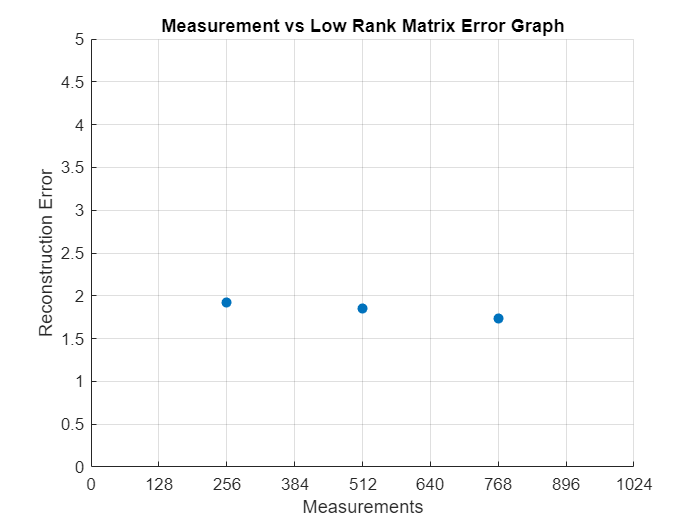

x = [0.25*1024 0.5*1024 0.75*1024];
y1 = [rec_err25L rec_err50L rec_err75L];
y2 = [rec_err25S rec_err50S rec_err75S];
y3 = [f25_t f50_t f75_t];


figure
scatter(x,y1,'o','filled');
xticks([0:128:1024])
yticks([0:0.5:5])
xlim([0 1024])
ylim([0 5])
xlabel('Measurements')
ylabel('Reconstruction Error')
title('Measurement vs Low Rank Matrix Error Graph')
grid on

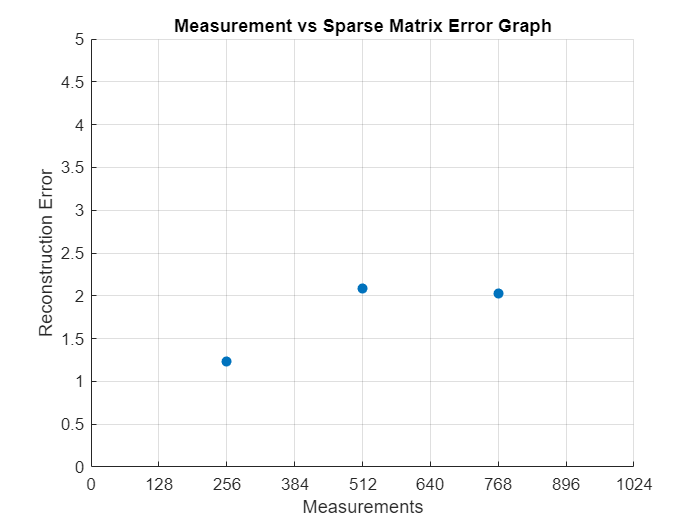

figure
scatter(x,y2,'o','filled');
xticks([0:128:1024])
yticks([0:0.5:5])
xlim([0 1024])
ylim([0 5])
xlabel('Measurements')
ylabel('Reconstruction Error')
title('Measurement vs Sparse Matrix Error Graph')
grid on

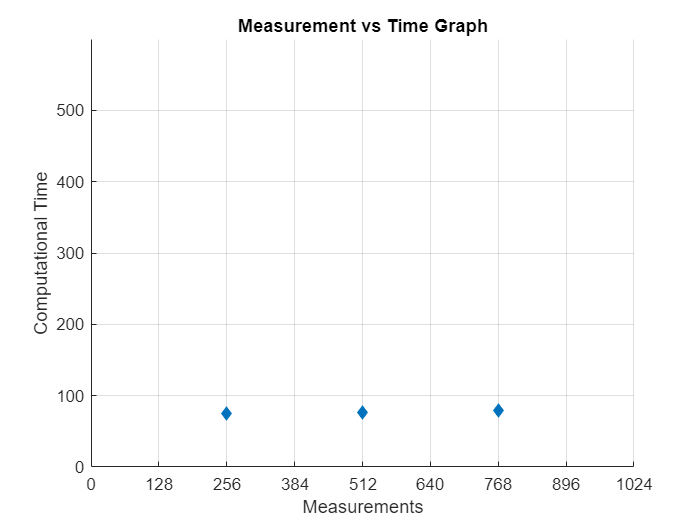


figure
scatter(x,y3,'d','filled');
xticks([0:128:1024])
yticks([0:100:500])
xlim([0 1024])
ylim([0 600])
xlabel('Measurements')
ylabel('Computational Time')
title('Measurement vs Time Graph')
grid on

## Functions

function [L,S,f_time] = tnn_admm(X,eps,rho,max_iter)
    [L,S,Y,U,V,A,B] = deal(cell(size(X)));
    k = length(X);
    mu_m = 1e10;
    mu = zeros(k,1);
    [m,n] = size(X{1});
    lam = 1/sqrt(max(m,n));
    tic
    for i = 1:k
        mu(i) = 0.25/mean(X{i}(:));
        X_hat = X{i};
        L_hat = zeros(size(X_hat));
        S_hat = zeros(size(X_hat));
        Y_hat = zeros(size(X_hat));
        [U{i},~,V{i}] = svds(X_hat,(min(m,n)-rank(X_hat)));
        A{i} = U{i}.';
        B{i} = V{i}.';
        iter = 1;
        while iter<max_iter
            iter = iter+1;
            % Calculate L
            L_hat = svt((X_hat - S_hat + (1/mu(i))*(Y_hat-A{i}.'*B{i})),1/mu(i));
            
            % Calculate S
            S_hat = shrink(X_hat - L_hat + (Y_hat/mu(i)),lam/mu(i));

            % Calculate Y
            Y_hat = Y_hat + mu(i)*(X_hat-L_hat-S_hat);

            % Update mu
            mu(i+1) = min(rho*mu(i),mu_m);

            l_err = norm(X_hat-L_hat,'fro')/norm(X_hat,'fro');
            s_err = norm(X_hat-S_hat,'fro')/norm(X_hat,'fro');
            if (l_err<=eps) && (s_err<=eps)
                break;
            end
        end
        L{i} = L_hat;
        S{i} = S_hat;
        Y{i} = Y_hat;
    end
    f_time = toc;
end

function E = shrink(s,tau)
    E = sign(s).*(max(0,abs(s)-tau));
end

function W = svt(Q,mu)
    [U_q,S_q,V_q] = svd(Q);
    mu_s = mu*eye(size(S_q));
    S_m = max(S_q-mu_s,0);
    W = U_q*S_m*V_q.';
end

function rec_err = err(A,ref)
    rec_err = zeros(size(ref));
    k = length(A);
    for i = 2:k
        rec_err(i-1) = norm(A{i}-ref{i-1},'fro')/norm(ref{i-1},'fro');
    end
end